# Time-Domain Statistical Features

Tutorial 1: Time-Domain Features of a Simple Sinewave

## Dataset

### Generate Signals

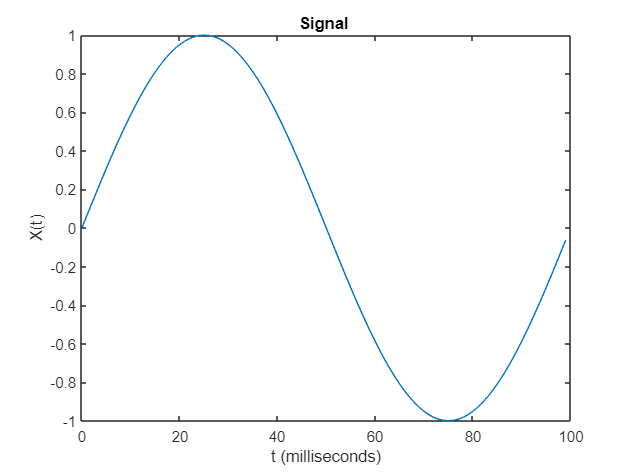

close all
clear 

Fs = 1000;                % Sampling frequency                    
T = 1/Fs;                 % Sampling period       
N = 100;                  % Length of signal
t = (0:N-1)*T;            % Time vector


% Information Signal 
fa=10;      % 10Hz signal
fa2=55;     % 55Hz signal
X = 0.0 + 1 * sin(2.0*pi*fa*t)+0*sin(2.0*pi*fa2*t); 

% Plot signals
figure()
plot(1000*t,X)
title('Signal ')
xlabel('t (milliseconds)')
ylabel('X(t)')

### Mix Signal with Noise

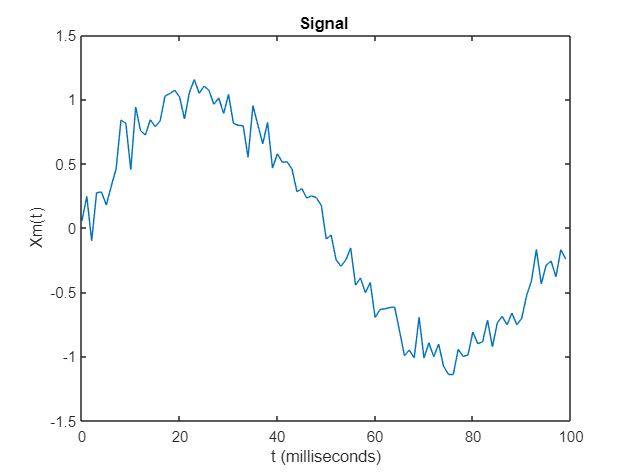


% Noise
noise=0.1*randn(size(t));

% Mixed Signal
Xm = 1 * sin(2.0*pi*fa*t)+noise; 


% Plot signals
figure()
plot(1000*t,Xm)
title('Signal ')
xlabel('t (milliseconds)')
ylabel('Xm(t)')

## Exercise1(answer):  Time-Domain Features  

Obtain the following features in time domain. Compare your code with MATLAB functions

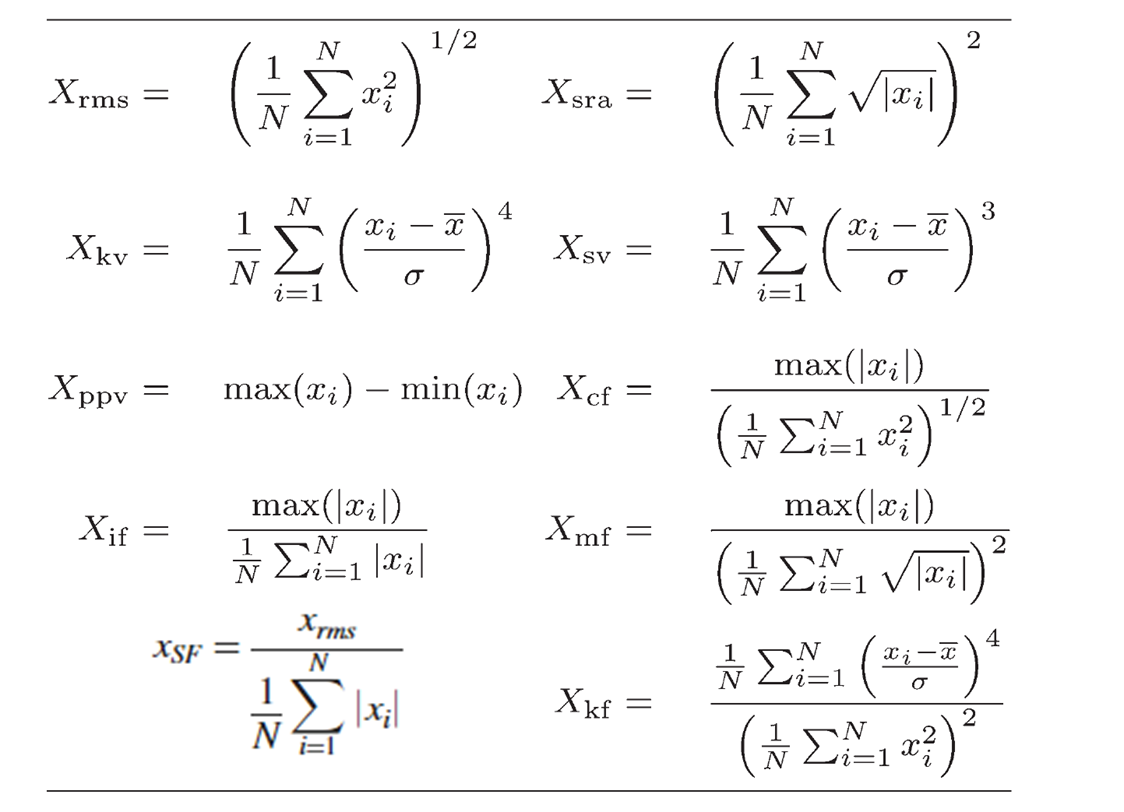

% x:        Input data
% xfeature: Table for feature of x

x=X;        %=Xm
xfeature = table;
N=length(x);


%% mean and STD
xfeature.mean = mean(x);
xfeature.std = std(x);

%% RMS
xfeature.rms = rms(x);

xrms = sqrt(sum(power(x,2))/N)

xrms = 0.7071

%% Square Root Average
% Your code
xfeature.sra = power((sum(sqrt(abs(x)))/N),2)

xfeature = 1×4 table
       mean         std        rms        sra  
    __________    _______    _______    _______

    3.0947e-17    0.71067    0.70711    0.57863


%% Average of Absolute Value
xfeature.aav=sum(abs(x))/N;
xfeature

xfeature = 1×5 table
       mean         std        rms        sra        aav  
    __________    _______    _______    _______    _______

    3.0947e-17    0.71067    0.70711    0.57863    0.63641


%% Energy (sum of power_2)
xfeature.energy=sum(x.^2);

%% Peak
xfeature.peak = max(x);

%% Peak2Peak
xfeature.ppv=peak2peak(x);

%% Impulse Factor
xfeature.if=xfeature.peak/xfeature.aav;

%% Shape Factor
xfeature.sf=xfeature.rms/xfeature.aav;

%% Crest Factor
%**** Your code goes here ****
xfeature.cf = max(abs(x))/xfeature.rms;
% Marginal(Clearance) Factor
xfeature.mf = xfeature.peak/xfeature.sra;

%% Skewness
xfeature.sk = skewness(x);

xsk = mean(((x - xfeature.mean)/xfeature.std).^3);
%% Kurtosis
xfeature.kt=kurtosis(x);
%**** Your code goes here ****
xkt = mean(((x - xfeature.mean)/xfeature.std).^4)

xkt = 1.4702

% Print all features
xfeature

xfeature = 1×14 table
       mean         std        rms        sra        aav      energy    peak    ppv      if        sf        cf        mf          sk         kt 
    __________    _______    _______    _______    _______    ______    ____    ___    ______    ______    ______    ______    ___________    ___

    3.0947e-17    0.71067    0.70711    0.57863    0.63641      50       1       2     1.5713    1.1111    1.4142    1.7282    -1.2381e-16    1.5


## Exercise 2

Compare the time-domain features with and without noise added.

## Exercise 3

Create a function that returns time-domain features in table form

Example: 

xfeature = timeFeatures(x)

xfeature = 1×14 table
       mean         std        rms        sra        aav      energy    peak    ppv      if        sf        cf        mf          sk         kt 
    __________    _______    _______    _______    _______    ______    ____    ___    ______    ______    ______    ______    ___________    ___

    3.0947e-17    0.71067    0.70711    0.57863    0.63641      50       1       2     1.5713    1.1111    1.4142    1.7282    -1.2381e-16    1.5
